# Objekt


clf
clear all

m = load("AK2P-G8-avbildningar.mat")

m = struct with fields:
    A: [2×2 double]
    B: [2×2 double]
    C: [2×2 double]


m.A

ans =    -0.8660   -0.5000
    0.5000   -0.8660



%m.A(1, 1) m.A(1, 2)
%m.A(2, 1) m.A(2, 2)

m.B

ans =     1.0000   -0.4000
         0    1.0000


m.C

ans =     0.0670    0.2500
    0.2500    0.9330


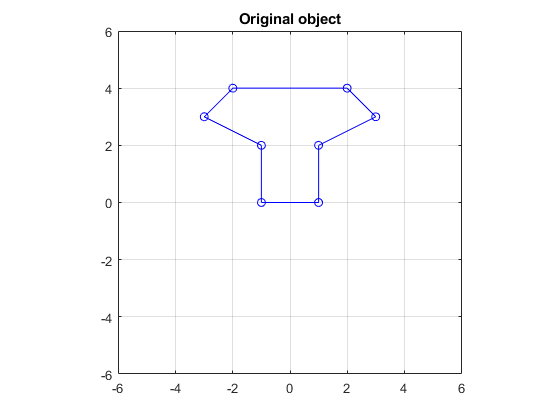


X=[1 1 3 2 -2 -3 -1 -1 1
    0 2 3 4 4 3 2 0 0
    0 0 0 0 0 0 0 0 0];

plot(X(1,:),X(2,:),'b-o')

axis equal

xlim([-6 6]);
ylim([-6 6]);
title("Original object")

grid on

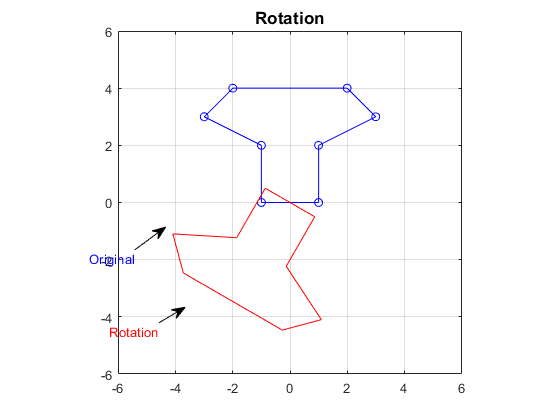



v=pi/4;
z=[cos(v) -sin(v)
    sin(v) cos(v)];

y1=m.A(1, 1)*X(1,:) + m.A(1, 2)*X(2,:);
y2=m.A(2, 1)*X(1,:) + m.A(2, 2)*X(2,:);

one_operation(X(1,:),X(2,:),y1,y2, "Rotation", "Original", "Rotation")
xlim([-6 6]);
ylim([-6 6]);


z1=m.B(1, 1)*X(1,:) + m.B(1, 2)*X(2,:);
z2=m.B(2, 1)*X(1,:) + m.B(2, 2)*X(2,:);

m.B

ans =     1.0000   -0.4000
         0    1.0000


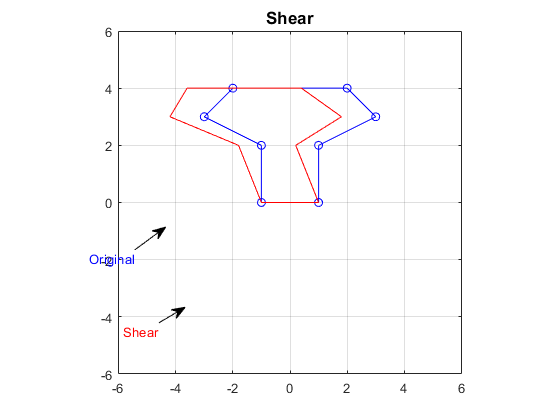


one_operation(X(1,:),X(2,:),z1,z2, "Shear", "Original", "Shear")
xlim([-6 6]);
ylim([-6 6]);

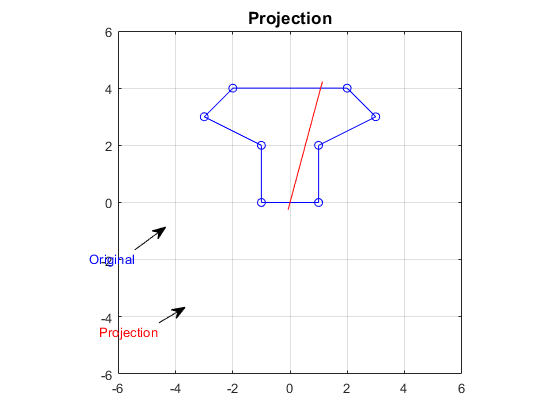


c1=m.C(1, 1)*X(1,:) + m.C(1, 2)*X(2,:);
c2=m.C(2, 1)*X(1,:) + m.C(2, 2)*X(2,:);

one_operation(X(1,:),X(2,:),c1,c2, "Projection", "Original", "Projection")
xlim([-6 6]);
ylim([-6 6]);


v = atan((c2(2)-c2(1)) / (c1(2)-c1(1)))

v = 1.3090



comp1=m.A(1, 1)*z1 + m.A(1, 2)*z2

comp1 =    -0.8660   -1.1732   -3.0588   -2.3464    1.1177    2.1373    0.5588    0.8660   -0.8660


comp2=m.A(2, 1)*z1 + m.A(2, 2)*z2

comp2 =     0.5000   -1.6321   -1.6981   -3.2641   -5.2641   -4.6981   -2.6321   -0.5000    0.5000





two_operations(X(1,:),X(2,:),z1,z2,comp1,comp2,"Composite Transformation" ,"Original", "Shear", "Sheared then rotated")

axes1 =   Axes (Composite Transformation) with properties:

             XLim: [-5.2321 4.0321]
             YLim: [-5.2641 4]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


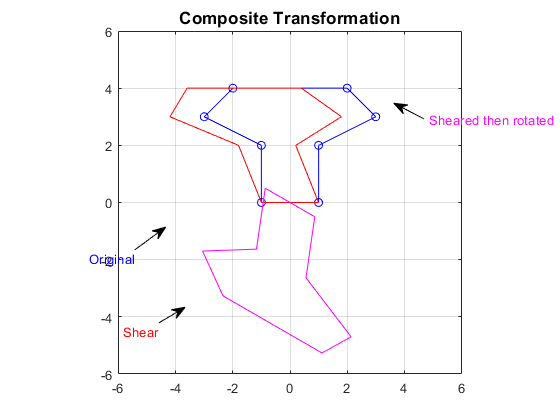

xlim([-6 6]);
ylim([-6 6]);

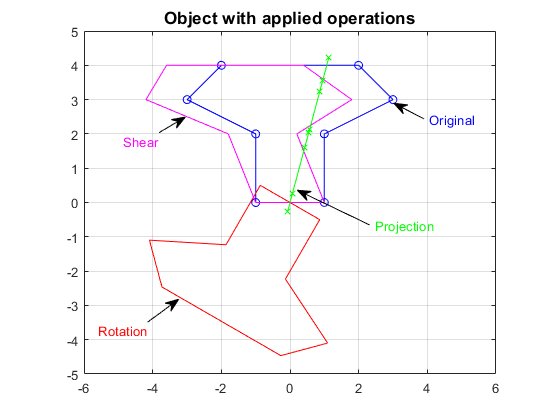



figure_all_operations(X(1,:),X(2,:),y1,y2,z1,z2,c1,c2)

xlim([-6 6]);
ylim([-5 5]);